# LAB_SHEET_6 CSE23239

a1 = 1;
a2=1;
q1 =0.2;
q2=0.3;
trchain2('R(q1),Tx(a1),R(q2),Tx(a2)',[q1,q2])

ans =     0.8776   -0.4794    1.8576
    0.4794    0.8776    0.6781
         0         0    1.0000


syms q1 q2 a1 a2
trchain2('R(q1),Tx(a1),R(q2),Tx(a2)',[q1,q2])

$$ans = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{1} & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & a_{2}\,\sigma_{1}+a_{1}\,\cos\left(q_{1}\right)\\ \cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \sigma_{1} & a_{2}\,\left(\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\right)+a_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) \end{array}$$

syms q1 q2 q3 a1 a2 a3
trchain2('R(q1),Tx(a1),R(q2),Tx(a2),R(q3),Tx(a3)',[q1 q2 q3])

$$ans = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{1} & -\cos\left(q_{3}\right)\,\sigma_{4}-\sin\left(q_{3}\right)\,\sigma_{3} & a_{2}\,\sigma_{3}+a_{1}\,\cos\left(q_{1}\right)+a_{3}\,\sigma_{1}\\ \sigma_{2} & \sigma_{1} & a_{2}\,\sigma_{4}+a_{1}\,\sin\left(q_{1}\right)+a_{3}\,\sigma_{2}\\ 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{3}\right)\,\sigma_{3}-\sin\left(q_{3}\right)\,\sigma_{4}\\ \sigma_{2}=\cos\left(q_{3}\right)\,\sigma_{4}+\sin\left(q_{3}\right)\,\sigma_{3}\\ \sigma_{3}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{4}=\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) \end{array}$$

syms q1 q2 q3 q4 a1 a2 a3 a4
trchain('Rz(q1),Tz(a1),Ry(q2),Ty(a2),Ry(q3),Tz(a3),Ry(q4),Tz(a4)',[q1,q2,q3,q4])

$$ans = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(q_{4}\right)\,\sigma_{7}-\sin\left(q_{4}\right)\,\sigma_{6} & -\sin\left(q_{1}\right) & \sigma_{2} & a_{4}\,\sigma_{2}-a_{2}\,\sin\left(q_{1}\right)+a_{3}\,\sigma_{6}\\ -\cos\left(q_{4}\right)\,\sigma_{5}-\sin\left(q_{4}\right)\,\sigma_{4} & \cos\left(q_{1}\right) & \sigma_{1} & a_{3}\,\sigma_{4}+a_{4}\,\sigma_{1}+a_{2}\,\cos\left(q_{1}\right)\\ -\cos\left(q_{4}\right)\,\sigma_{9}-\sin\left(q_{4}\right)\,\sigma_{8} & 0 & \sigma_{3} & a_{1}+a_{3}\,\sigma_{8}+a_{4}\,\sigma_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{4}\right)\,\sigma_{4}-\sin\left(q_{4}\right)\,\sigma_{5}\\ \sigma_{2}=\cos\left(q_{4}\right)\,\sigma_{6}+\sin\left(q_{4}\right)\,\sigma_{7}\\ \sigma_{3}=\cos\left(q_{4}\right)\,\sigma_{8}-\sin\left(q_{4}\right)\,\sigma_{9}\\ \sigma_{4}=\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{5}=\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\\ \sigma_{6}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ \sigma_{7}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{8}=\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{9}=\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) \end{array}$$

import ETS2.*
a1 = 1;a2=1;
E = Rz('q1')*Tx(a1)*Rz('q2')*Tx(a2)

 
E = 
Rz(q1)Tx(1)Rz(q2)Tx(1)


creating new ETS plot


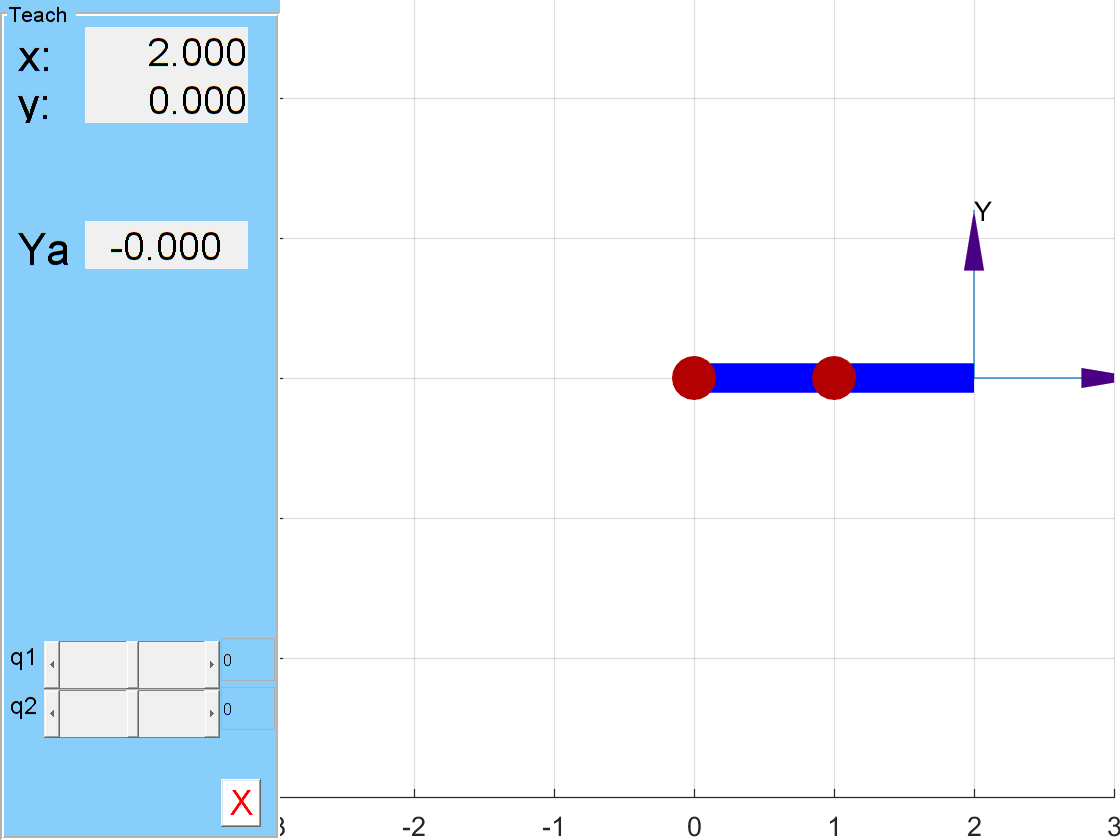

E.teach

E.fkine([30 40],'deg')

 

ans = 
    0.3420   -0.9397     1.208
    0.9397    0.3420      1.44
         0         0         1


creating new ETS plot


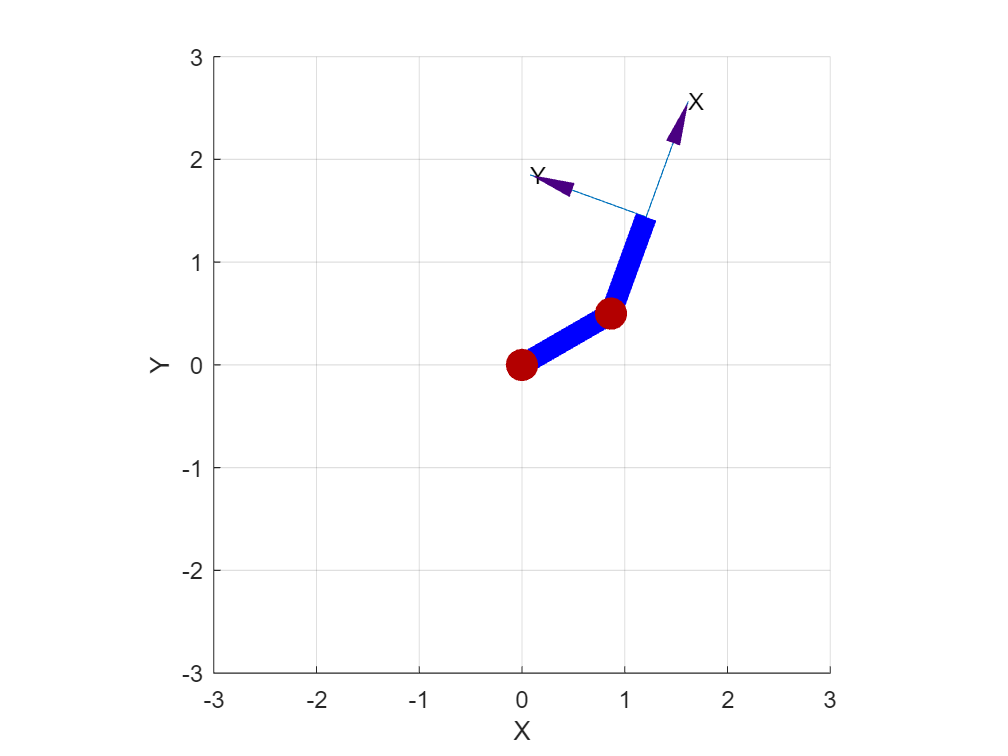

E.plot([30,40],'deg')

E.structure

ans = 'RR'

import ETS2 m.*
a1=1;
E = Rz('q1')*Tx(a1)*Tx('q2')

 
E = 
Rz(q1)Tx(1)Tx(q2)


E.structure

ans = 'RP'

creating new ETS plot


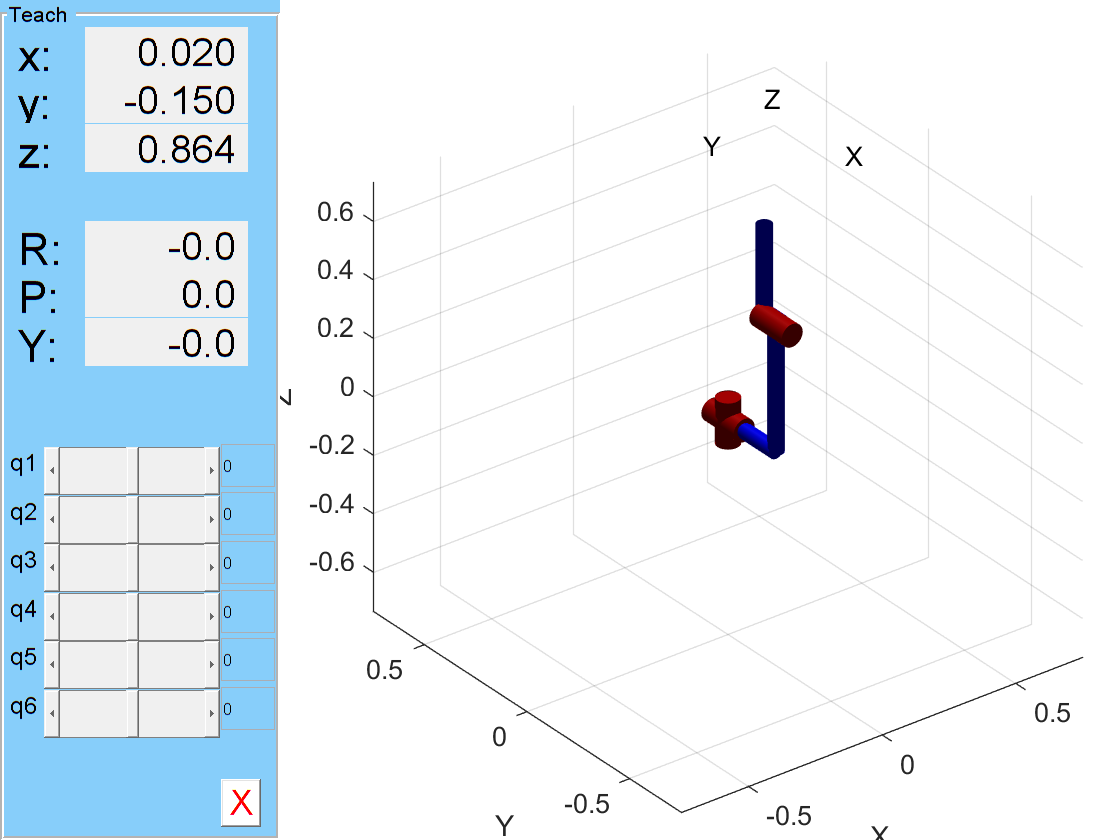

import ETS3.*
L1 = 0; L2 = -0.2337; L3 = 0.4318; L4 = 0.0203; L5 = 0.0837; L6 =0.4318;
E3 = Tz(L1) * Rz('q1') * Ry('q2') * Ty(L2) * Tz(L3) * Ry('q3')*Tx(L4) * Ty(L5) * Tz(L6) * Rz('q4') * Ry('q5') * Rz('q6');

E3.teach